This script is to illustrate how online adaptation can improve real time prediction. The adaptation algorithm implemented in nonlinear recursive least square, which is equivalent to extended kalman filter. 

First, we specify the system and its gradient w.r.t. to the parameter

f = @(a,x) a*sin(a*x); % dynamics x(k+1) = f(x(k))
g = @(a,x) sin(a*x)+a*cos(a*x)*x; % gradient 

Specification of the time varying parameter

p = @(t) 1+0.01*t-0.0001*t^2;

Initial conditions and ground truth trajectory

x0 = 1; % Initial state
T = 50; % Horizon
x = zeros(1,T+1); x(1) = x0;
a = zeros(1,T);
for t = 1:T
    a(t) = p(t);
    x(t+1) = f(a(t),x(t));
end

Visualization of the trajectory

figure; 
subplot(211)
hold on
plot(x, 'k', 'LineWidth', 2)
xlim([1,T+1])
title("System trajectory")
subplot(212)
hold on
plot(a, 'k', 'LineWidth', 2)
xlim([1,T+1])
title("System parameter")

Parameters for trajectory prediction

a0 = 1.6; % Initial estimation of the parameter
h = 9; % Prediction horizon
ADAPT =  true; % Adaptation or not
lambda = 0.8; % Forgetting factor in adaptation

Result for trajectory prediction

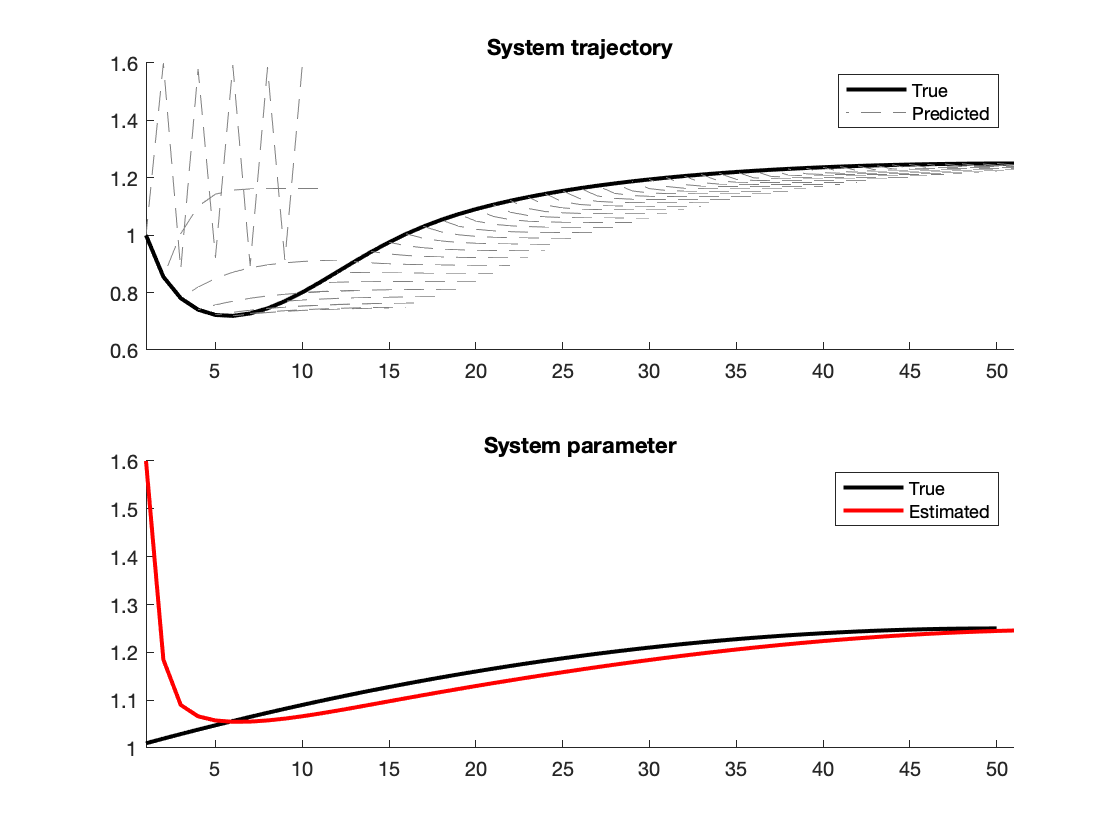

ahat = a0 * ones(1,T+1);
H = ones(1,T+1);
subplot(211)
for t = 2:T+1
    xhat = predict(f, ahat(t-1), x(t-1), h);
    if ADAPT
        error = x(t) - xhat(2);
        G = g(ahat(t-1), x(t-1));
        H(t) = lambda*H(t-1) + G'*G;
        ahat(t) = ahat(t-1) + inv(H(t))*G'*error;
    end
    plot(t-1:t+h-1, xhat,'--','color',[0.5,0.5,0.5])
end
legend("True","Predicted")
subplot(212)
plot(ahat,'r','LineWidth',2)
xlim([1,T+1])
legend("True","Estimated")